# Assessment 1b Data Fitting

H00368671

**Task 1: Annotate doc**

clear; % Clears all variables from the workspace

clc;   % Clears the command window

close all; % Closes all open figures

% Load the experimental data 

load('Speed_of_light_data.mat');

% Create the first figure 

figure(1)

% Plot the experimental data points with error bars

errorbar(time, distance, error*ones(size(distance)), 'red.','MarkerSize',20) 

% Add a legend, title, and axis labels to the plot 

legend('Data') 

title('Fitting to a straight line') 

xlabel('Time (seconds)');

ylabel('Distance (meters)');

% Define a linear model function for fitting: d = c * t + b

% b(1) represents the speed of light, and b(2) represents the intercept 

modelfun = @(b, x) b(1) * x + b(2); 

% Test the linear model with an initial guess [3e8, 0]

test_distance = modelfun([3e8 0], time); 

% Create a second figure

figure(2)

% Plot the test model 

plot(time, test_distance, 'blue-') 

% Add legend, title, and axis labels

legend('Test of model') 

title('Test of model') 

xlabel('Time (seconds)');

ylabel('Distance (meters)');

% Create the third figure 

figure(3)

hold on % Allows multiple plots on the same graph 

% Plot the test model 

plot(time, test_distance, 'blue-') 

% Plot the experimental data with error bars 

errorbar(time, distance, error*ones(size(distance)), 'red.','MarkerSize',20) 

% Add legend, title, and axis label

legend('Test of model', 'Data') 

title('Test of model') 

xlabel('Time (seconds)');

ylabel('Distance (meters)');

hold off % Ends the hold

% Initial guess is [3e8, 0]

start = [3e8 0];

% 'fitnlm' takes the independent variable, dependent variable, the model function, and the initial guess for %parametersand fits the data

mdl = fitnlm(time, distance, modelfun, start);

% Create the fourth figur

figure(4)

hold on 

% Plot the experimental data with error bars

errorbar(time, distance, error.*ones(size(distance)), 'red.','MarkerSize',20) 

% Plot the fited model

% 'predict' uses the fitted model to compute predicted distances for the given times

plot(time, predict(mdl, time'), 'red--') 

% Plot the theoretical model 

plot(time, 3e8 * time, 'red-')

% Add legend, title, and axis labels to the plot

legend('Data', 'Fit', 'Theory with c = 3e8') 

title('Fitting to a straight line') 

xlabel('Time (seconds)');

ylabel('Distance (meters)');

hold off 

% mdl.Coefficients contains the estimated parameters and their associated errors

estimate_c = mdl.Coefficients{1,1}; % The first coefficient corresponds to the slope,

error_on_c = mdl.Coefficients{1,2}; % The second column contains the standard error

% Calculate the number of standard deviation

number_of_standard_deviations = (3e8 - estimate_c) / error_on_c;

% Calculate the chi-squared value to evaluate the goodness

% Chi-squared is the sum of the squared residuals normalized by the error on the data

% Residuals = (predicted distance - observed distance)

chisq = sum(((predict(mdl, time')' - distance) ./ (error*ones(size(distance)))).^2);

% Calculate the chi-squared per degree of freedom

% Degrees of freedom = number of data points - number of fitted parameters

chisq_per_dof = chisq / 8; % Assuming 8 data points (time) and 2 parameters (c and b)

**Task 2: Fitting a Gaussian**

% Load the data for Gaussian fitting
load('Gaussian_data.mat'); % Assuming it contains variables 'x' and 'Amplitude'

% Plot the data to visually inspect it
figure;
plot(x, Amplitude, 'o'); % Plotting x vs. Amplitude
xlabel('x');
ylabel('Amplitude');
title('Data for Gaussian Fit');

% Define the Gaussian fitting function
gauss_fun = @(p, x) p(1) * exp(-(x - p(2)).^2 / (2 * p(3)^2)) + p(4); 
% p(1) = a (amplitude), p(2) = x0 (center), p(3) = sigma (width), p(4) = b (baseline)

% Initial guesses for the parameters [a, x0, sigma, b]
initial_guess = [max(Amplitude), mean(x), std(x), min(Amplitude)];

% Perform the fit using lsqcurvefit
% The lsqcurvefit function minimizes the difference between the model and data
[fit_params, resnorm, residual, exitflag, output, lambda, J] = lsqcurvefit(gauss_fun, initial_guess, x, Amplitude);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


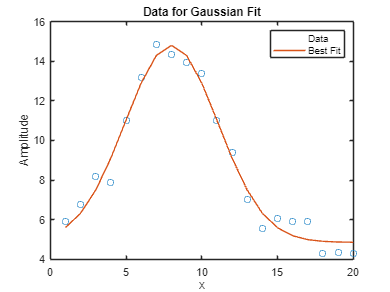


% Convert any sparse matrices to full matrices
J = full(J); % Ensure that J is full and not sparse to avoid issues with matrix inversion

% Plot the best-fit function along with the data
hold on;
plot(x, gauss_fun(fit_params, x), '-'); % Plot the fitted Gaussian
legend('Data', 'Best Fit');
hold off;


% Compute the chi-square value (goodness of fit)
chi_squared = sum((residual).^2); 
dof = length(x) - length(fit_params); % Degrees of freedom (N - M)

% Calculate the errors on the parameters
% inv(J' * J) computes the covariance matrix, and the square root of diagonal elements gives the parameter errors
errors = sqrt(diag(inv(J' * J))); 

% Display the fitted parameters and their errors using disp
disp('Fitted parameters:');

Fitted parameters:


disp(['a = ', num2str(fit_params(1)), ' ± ', num2str(errors(1))]); % Amplitude

a = 9.9494 ± 0.63032


disp(['x0 = ', num2str(fit_params(2)), ' ± ', num2str(errors(2))]); % Center

x0 = 7.9956 ± 0.18754


disp(['sigma = ', num2str(fit_params(3)), ' ± ', num2str(errors(3))]); % Width (sigma)

sigma = 3.0713 ± 0.26346


disp(['b = ', num2str(fit_params(4)), ' ± ', num2str(errors(4))]); % Baseline

b = 4.8521 ± 0.45763


disp(['Chi-squared/DOF: ', num2str(chi_squared/dof)]);

Chi-squared/DOF: 0.42344



% Adjust the error bars to achieve chi^2/DOF = 1
adjusted_error = sqrt(resnorm / dof);
disp(['The adjusted error to achieve chi^2/DOF = 1 is: ', num2str(adjusted_error)]);

The adjusted error to achieve chi^2/DOF = 1 is: 0.65072


**Task 3: Calc error on the parameter**

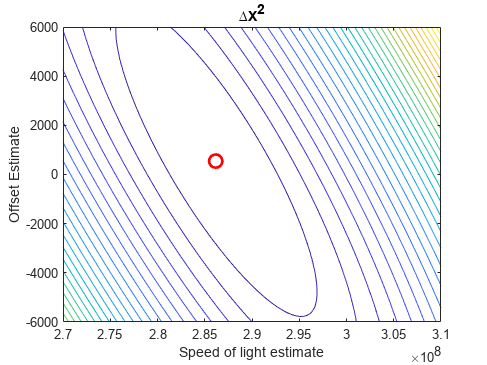


 % Define the model function for fitting 

modelfun = @(b, x) b(1) * x + b(2); 

 

% Define a range of values for the slope (b1) and intercept (b2) 

b1_range = linspace(2.7e8, 3.1e8, 100); % Adjust the range as needed 

b2_range = linspace(-6000, 6000, 100);   % Adjust the range as needed 

 

% Create a grid of b1 and b2 values 

[B1, B2] = meshgrid(b1_range, b2_range); 

 

% Initialize an array to store chi-squared values 

chisq_values = zeros(size(B1)); 

 

% Calculate chi-squared values for different combinations of b1 and b2 

for i = 1:numel(B1) 

    test_distance = modelfun([B1(i), B2(i)], time); 

    residuals = (test_distance - distance) ./ (error * ones(size(distance))); 

    chisq_values(i) = sum(residuals.^2); 

end 

 

% Reshape chi-squared values to match the grid 

chisq_values = reshape(chisq_values, size(B1)); 

 

% Create a contour plot of chi-squared values 

figure; 

contour(B1, B2, chisq_values, 30); % Adjust the number of contour levels as needed 

 

% Add labels and a title 

xlabel('Speed of light estimate'); 

ylabel('Offset Estimate'); 

title('∆X^2'); 

 

% Find the minimum chi-squared value and its corresponding parameters 

[min_chisq, min_idx] = min(chisq_values(:)); 

[min_b1, min_b2] = ind2sub(size(chisq_values), min_idx); 

 

% Overlay the minimum chi-squared point on the contour plot 

hold on; 

plot(B1(min_b1, min_b2), B2(min_b1, min_b2), 'ro', 'MarkerSize', 10, 'LineWidth', 2); 

hold off; 


 

% Display the minimum chi-squared point and its parameters 

fprintf('Minimum Chi-Squared Value: %.4f\n', min_chisq); 

Minimum Chi-Squared Value: 8.4835



fprintf('Best-Fit Slope (b1): %.4f\n', B1(min_b1, min_b2)); 

Best-Fit Slope (b1): 286161616.1616



fprintf('Best-Fit Intercept (b2): %.4f\n', B2(min_b1, min_b2)); 

Best-Fit Intercept (b2): 545.4545
